n = k1/k = c/c1, m = rho_1/rho

Reflection from a Lower Velocity, Less Dense Half Space (Water-Air interface) 

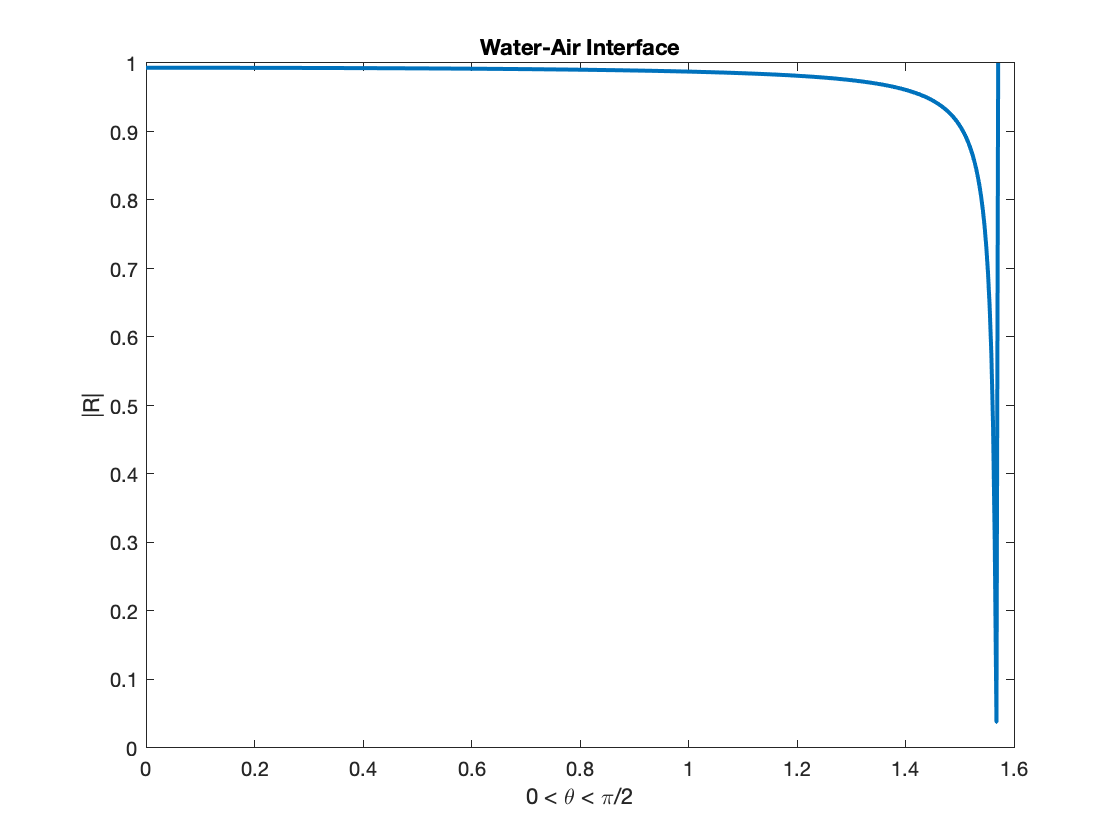

rho = 1;
rho_1 = 1.3 * 10^3;
c = 1500;
c1 = 332;
n = c/c1;
m = rho_1/rho;

theta = 0:pi/1000:pi/2;
y = (rayleigh(m,n,theta));
plot(theta, abs(y), 'LineWidth', 2)
xlabel('0 < \theta < \pi/2')
ylabel('|R|')
title("Water-Air Interface")

Reflection from a lower velocity, more dense half space (the water bottom interface: model 1)

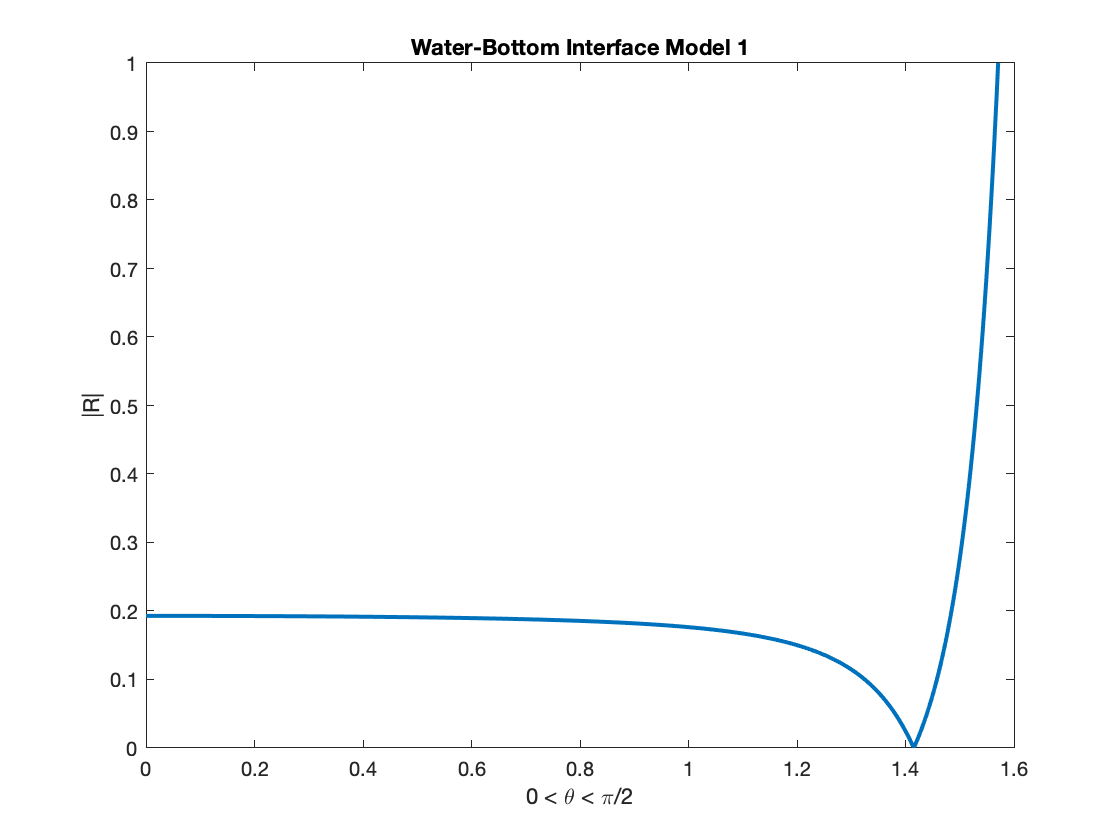

rho_1 = 1.5;
c1 = 1478;
n = c/c1;
m = rho_1/rho;

theta = 0:pi/1000:pi/2;
y = (rayleigh(m,n,theta));
plot(theta, abs(y),'LineWidth',2)
xlabel('0 < \theta < \pi/2')
ylabel('|R|')
title("Water-Bottom Interface Model 1")

Reflection from a Higher Velocity, More Dense Half-Space (the water bottom interface: model 2)

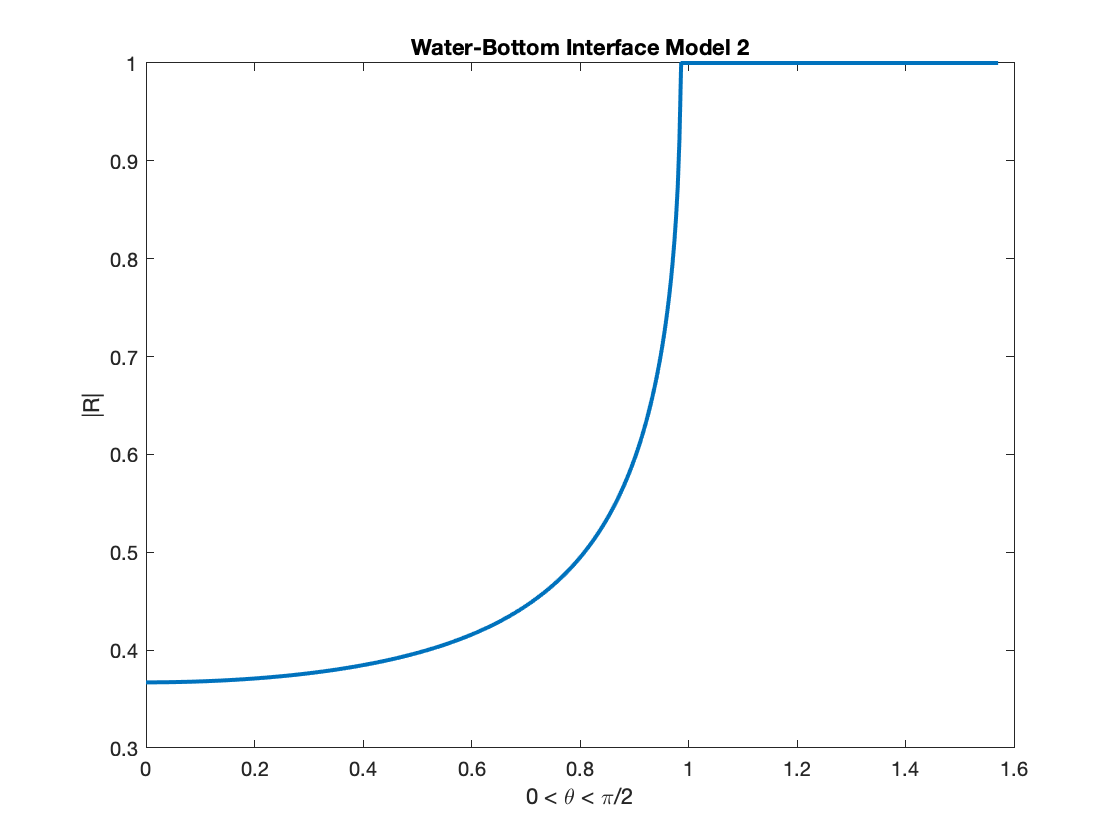

rho_1 = 1.8;
c1 = 1800;
n = c/c1;
m = rho_1/rho;

theta = 0:pi/1000:pi/2;
y = (rayleigh(m,n,theta));
plot(theta, abs(y),'LineWidth',2)
xlabel('0 < \theta < \pi/2')
ylabel('|R|')
title("Water-Bottom Interface Model 2")

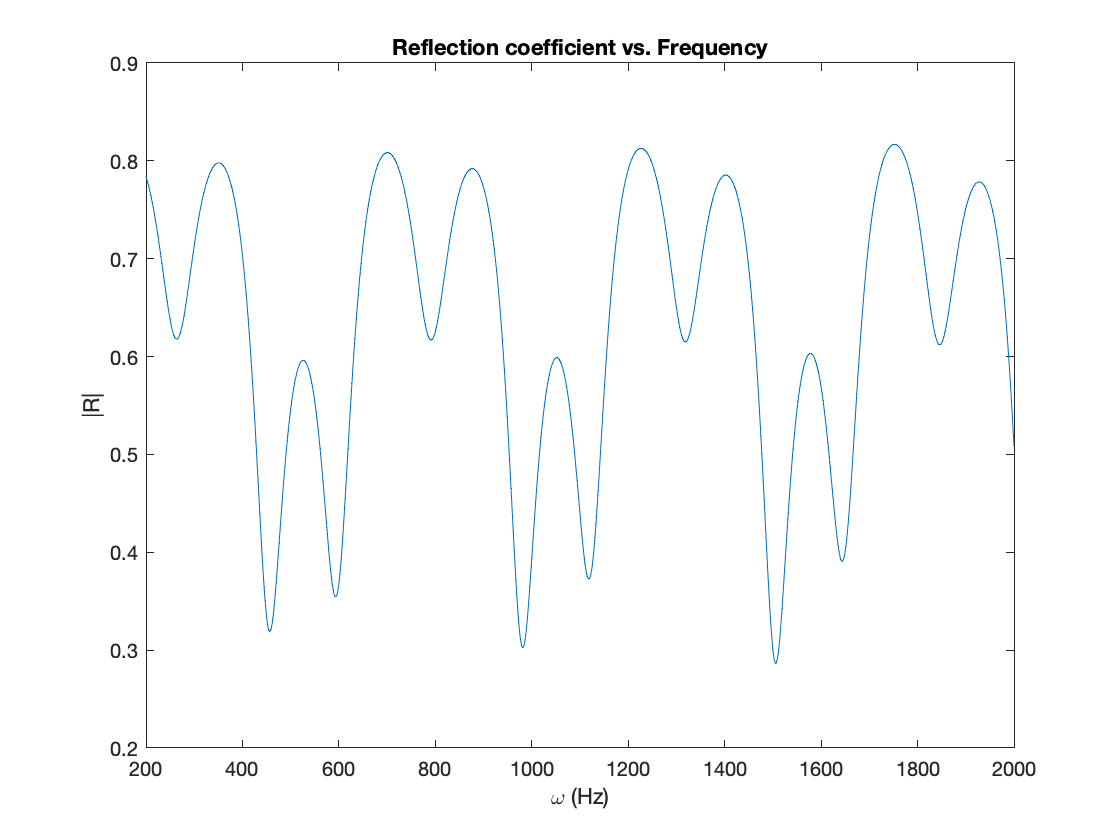

%test with random coefficients
rho = [3;2;.8;.9;1];
c = [1400; 1200; 1300; 1800; 1100];
h = [20;30;8];
freq = 200;
theta = pi/8;

R_array = rayleigh_strat(rho,c,h,theta,freq);

%a = fliplr(a)

freq_range = 200:2000;
R_vec = zeros(2000-200,1);
for freq = 200:2000
    R_array = rayleigh_strat(rho,c,h,theta,freq);
    R_vec(freq-199) = R_array(1);
end

plot(freq_range, abs(R_vec))
xlabel("\omega (Hz)")
ylabel('|R|')
title("Reflection coefficient vs. Frequency")